# Assignment 7 in ModSim

#### By Alexander Rambech

### Task 1

**a)**

We place $k_1$ and $k_2$ into $x_{k+1}$ and get:

- 
$$x_{k+1} = x_k + \Delta t \cdot [b_1\cdot f(x_k,u(t_k), t_k) + b_2 \cdot f(x_k + a \cdot \Delta t \cdot k_1,u(t_k + c\Delta t), t_k+ c\Delta t)]$$


where 

- 
$$ f(x_k + a \cdot \Delta t \cdot k_1,u(t_k + c\Delta t) =  f(x(t_k), u_k) + a \Delta t \frac{\partial f}{\partial x} \left|_{x(t_k)} f(x(t_k), u_k) + O(\Delta t^2)$$


this yields:

- 
$$x_{k+1} = x_k + \Delta t \cdot b_1\cdot f(x_k,u(t_k), t_k) +  \Delta t \cdot b_2 \cdot [f(x(t_k), u_k) + a \Delta t \frac{\partial f}{\partial x} \left|_{x(t_k)} f(x(t_k), u_k) + O(\Delta t^2)] $$


- 
$$x_{k+1} = x(t_k) + \Delta t \cdot b_1\cdot f(x_k,u(t_k), t_k) +  \Delta t \cdot b_2 \cdot f(x(t_k), u_k) + a \cdot b_2 \cdot\Delta t^2 \frac{\partial f}{\partial x} \left|_{x(t_k)} f(x(t_k), u_k) + O(\Delta t^3)$$


We also know that $x(t_{k+1}) $ is given by:

- 
$$x(t_{k+1}) = x(t_k) + \Delta t \cdot f(x(t_k),u) + \frac{\Delta t^2}{2} \cdot \dot{f}(x(t_k),u_k )+ \mathcal{O}(\Delta t^3) $$


By using these two equations we have the conditions:

- 
$$0 \leq c \leq 1$$


- 
$$a\cdot b_2 = \frac{1}{2}$$


- 
$$b_1 + b_2 = 1$$


**b)**

$\mathcal{O}(\Delta t^3)$ refers to the local error while the order of $ERK2$ refers to the global error. To find the global error we have to relate the local error to the sampling time. In order to simulate using the Runga-Kutta method, it needs to run $N$ steps. Here the step amount is given by $N = \frac{t_{final}}{\Delta t}$, where $t_{final}$ is the last time step. The global error is then given by $e_{global} = \mathcal{O}(N\Delta t^3) =  \mathcal{O}(t_{final} \Delta t^2)$. This clearly illustrates why $ERK2$ is of maximum order $2$.

### Task 2

**a)**

Because MATLAB does function calls from the bottom up, the $ERKTemplate$ function is at the end of the assignement.

clear all;

% 
lambda = -2;
final_time = 2;
delta_t = 0.4;
x_0 = 1;
test_func = @(t, x) lambda*x;

n_steps = final_time/delta_t;
steps = 0:n_steps:final_time;

%rk1
A = 0; b = 1; c = 0;
rk1 = struct('A',A,'b',b,'c',c);

%rk2
A = [0  0; 1/2 0];
b = [0; 1];
c = [0; 1/2];
rk2 = struct('A',A,'b',b,'c',c);

%rk4
A = [0 0 0 0; 1/2 0 0 0; 0 1/2 0 0; 0 0 1 0];
b = [1/6; 1/3; 1/3; 1/6];
c = [0; 1/2; 1/2; 1];
rk4 = struct('A',A,'b',b,'c',c);

%% Simulate
x_rk1 = ERKTemplate(rk1, test_func, steps, x_0);
x_rk2 = ERKTemplate(rk2, test_func, steps, x_0);
x_rk4 = ERKTemplate(rk4, test_func, steps, x_0);

%% Plot
figure(1)
hold on; grid on;
plot(steps, x_rk1, '-')
plot(steps, x_rk2, '-')
plot(steps, x_rk4, '-')

I am struggeling getting my code to work :((

**c)**

In general explicit RK methods are stable if and only if the order $|R(\lambda \Delta t)| \leq 1$. For RK 1, 2 and 4 this is then given by:

- $|1+\lambda\Delta t| \leq 1$,

- $|1+\lambda\Delta t^2 \frac{1}{2}| \leq 1$ and

- 
$$|1+\lambda\Delta t^2 \frac{1}{2} + \lambda\Delta t^3 \frac{1}{3} + \lambda\Delta t^4 \frac{1}{4}| \leq 1$$


, respectively.

### Task 3

**a)**

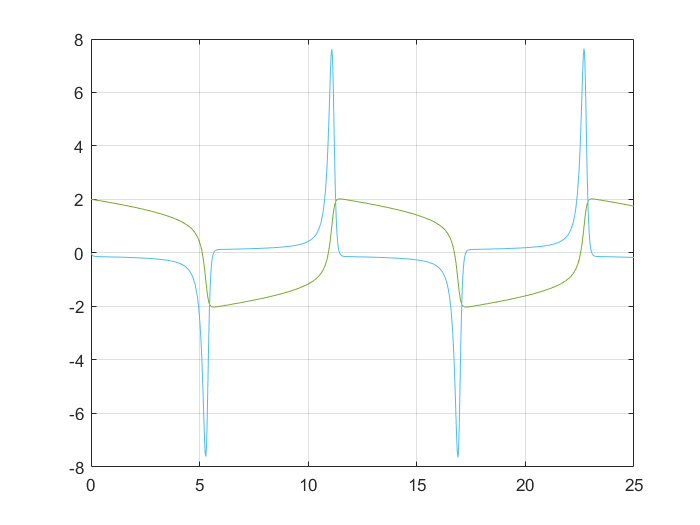

clear variables

% Initial condition
x_0 = [2 0];
VanDerPol = @(t, x) [x(2); 5*(1 - x(1)^2)*x(2)-x(1)];
[t, x] = ode45(VanDerPol,[0 25],x_0);

figure(2);
grid on; hold on;
plot(t, x)

We see the classic non-linear VanDerPol oscillator, which oscilallates with a certain period, but in a non-linear fashon. 

**b)**

For this part I need the ERKTemplate function that I could not get working in Task 2

function x = ERKTemplate(ButcherArray, f, T, x0)
    % Returns the iterations of an ERK method
    % ButcherArray: Struct with the ERK's Butcher array
    % f: Function handle
    %    Vector field of ODE, i.e., x_dot = f(t,x)
    % T: Vector of time points, 1 x Nt
    % x0: Initial state, Nx x 1
    % x: ERK iterations, Nx x Nt
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Define variables
    A = ButcherArray .A;
    b = ButcherArray .b;
    c = ButcherArray .c;
    
    nt = length(T); % Number of timesteps
    nx = length(x0); % Number of states
    kNstage = size(A,1); % Amount of stages
    K = zeros(nx, kNstage); % Making Ks
    
    x = zeros(nx, nt); % Allocating space for iterations
    x(:, 1) = x0; % Fist collumn in the x array are the initial values
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    dT = diff(T);
    xt = x0; % initial iteration
    % Loop over time points
    for i=2:nt
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        % Update variables
        t = T(i-1);
        dt = dT(i-1);
        K(:, 1) = f(t, xt);
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        % Loop that calculates k1,k2,...,kNstage
        for nstage=2:kNstage
            K(:,nstage) = f(nt, xt + dt * sum(K .* A(nstage,:),2) );
        end
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        % Calculate and save next iteration value x_t
        xt = xt + dt*K*b;
        x(:, nt) = xt;
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    end
end